clearvars; close all; clc;

# Closed box including ANSYS imported results

2024-06-07, JVsound, J.G. Vermond

## Introduction

A closed box system (and all other loudspeaker systems in the toolbox) can be simulated in different ways:

- Lumped and analytical elements: this can be done using only the toolbox

- Lumped elements for the electrical and mechanical part of the system, and import the acoustic impedances from an FEA (ANSYS) simulation. The resulting sound pressure level in the far-field is calculated by the toolbox.

- Equal to 2, only the sound pressure level is also calculated by imported results from ANSYS.

This livescript shows how the above is carried out, and will validate the results.

## Validation by Hornresp

We load some results (see Appendix A for the Hornresp inputs) exported by Hornresp to validate our results.

load closedboxvalspl.mat

## Driver

The driver for this simulation is the B&C 18SW115-8.

% Create woofer object:
wf			= speaker.woofer;
wf.brand	= "B&C";
wf.model	= "18SW115-8";
wf.size		= 18;

wf.re		= 5.3;
wf.qes		= 0.32;
wf.qms		= 5.6;
wf.fs		= 32;
wf.sd		= 1210e-4;
wf.vas		= 187e-3;

wf.le		= 1.9e-3;
wf.xmax		= 14e-3;
wf.paes		= 1700

wf =   woofer with properties:

    brand: "B&C"
    model: "18SW115-8"
     size: 18
       re: 5.3000
      qes: 0.3200
      qms: 5.6000
       fs: 32
       sd: 0.1210
      vas: 0.1870
       le: 0.0019
     xmax: 0.0140
     paes: 1700
      qts: 0.3027
      cms: 9.1045e-05
      kms: 1.0984e+04
      mms: 0.2717
      mmd: 0.2241
      rms: 9.7550
       bl: 30.0795
        a: 0.1963


## Simulation 1

Create a simulation object:

% Simulation object:
sim1		= acoustics.simulation;

% Assign frequencies:
sim1.f		= logspace(1,log10(2e4),1e3);

% Generator voltage:
sim1.eg		= 2.83;

% Distance to mic [m]:
sim1.r		= 1;

### Enclosure

Create an enclosure object with an internal volume of 150L.

% Enclosure object:
encl1		= enclosure.closedbox;

% Internal volume [m3]:
encl1.vol	= 150e-3;

### Results

Assign the enclosure and driver to the simulation object:

sim1.encl	= encl1;
sim1.sp		= wf;

The results are shown in the following figures:

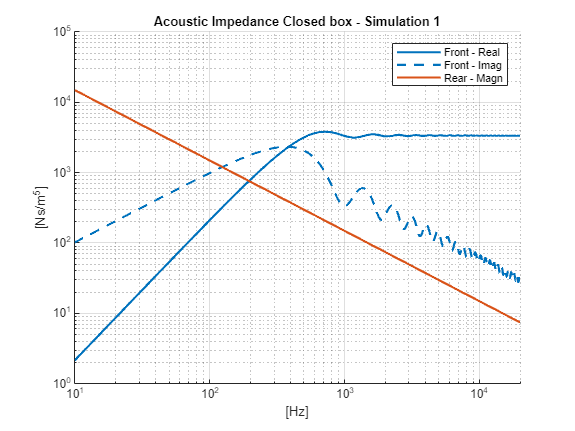

% Get SPL and Za:
spl			= sim1.spl;
za			= sim1.za;

% Figure 1 - Acoustic impedance
fig1				= figure;
ax1					= axes(fig1); hold on; grid on;
ax1.FontSize		= 8;
ax1.XScale			= "log";
ax1.XLim 			= [sim1.f(1) sim1.f(end)];
ax1.YScale			= "log";
ax1.Title.String	= "Acoustic Impedance Closed box - Simulation 1";
ax1.XLabel.String	= "[Hz]";
ax1.YLabel.String	= "[Ns/m^5]";

p1	= plot(ax1,sim1.f,real(za.front),LineWidth=1.5);
plot(ax1,sim1.f,imag(za.front),LineWidth=1.5,LineStyle="--",Color=p1.Color);

ax1.ColorOrderIndex = 2;

plot(ax1,sim1.f,abs(za.rear),LineWidth=1.5);

leg1		= legend(ax1,"Front - Real","Front - Imag","Rear - Magn");

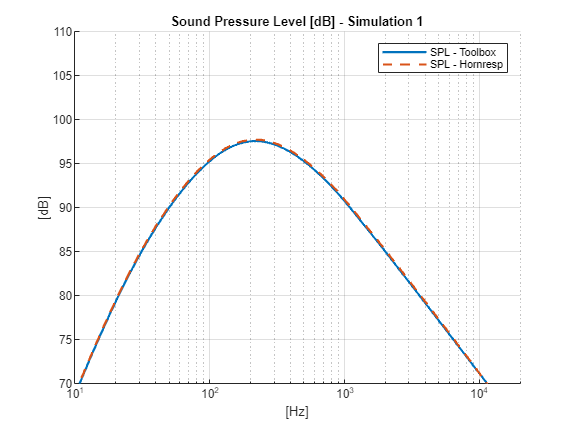


% Figure 2 - SPL
fig2				= figure;
ax2					= axes(fig2); hold on; grid on;
ax2.FontSize		= 8;
ax2.XScale			= "log";
ax2.XLim 			= [sim1.f(1) sim1.f(end)];
ax2.YLim 			= [70 110];
ax2.XLabel.String	= "[Hz]";
ax2.YLabel.String	= "[dB]";
ax2.Title.String	= "Sound Pressure Level [dB] - Simulation 1";

plot(ax2,sim1.f,spl,LineWidth=1.5);
plot(ax2,closedboxvalspl.Freqhertz,closedboxvalspl.SPLdB,LineWidth=1.5,LineStyle="--");

leg2 		= legend(ax2,"SPL - Toolbox","SPL - Hornresp");

The results are almost identical. The minor deviation is probably due to a different sound velocity and/or density of air.

## Simulation 2

This simulation is identical to simulation 1, only the acoustic impedance is imported from an ANSYS FEA model.

We copy the simulation object:

% Simulation 2 object:
sim2 		= sim1;

### Acoustic impedance by ANSYS

We create a quarter symmetry model, see below, and we request the pressure as function of frequency for the rear and front diaphragm. The velocity in x-direction for both sides of the diaphragm is 1mm/s.

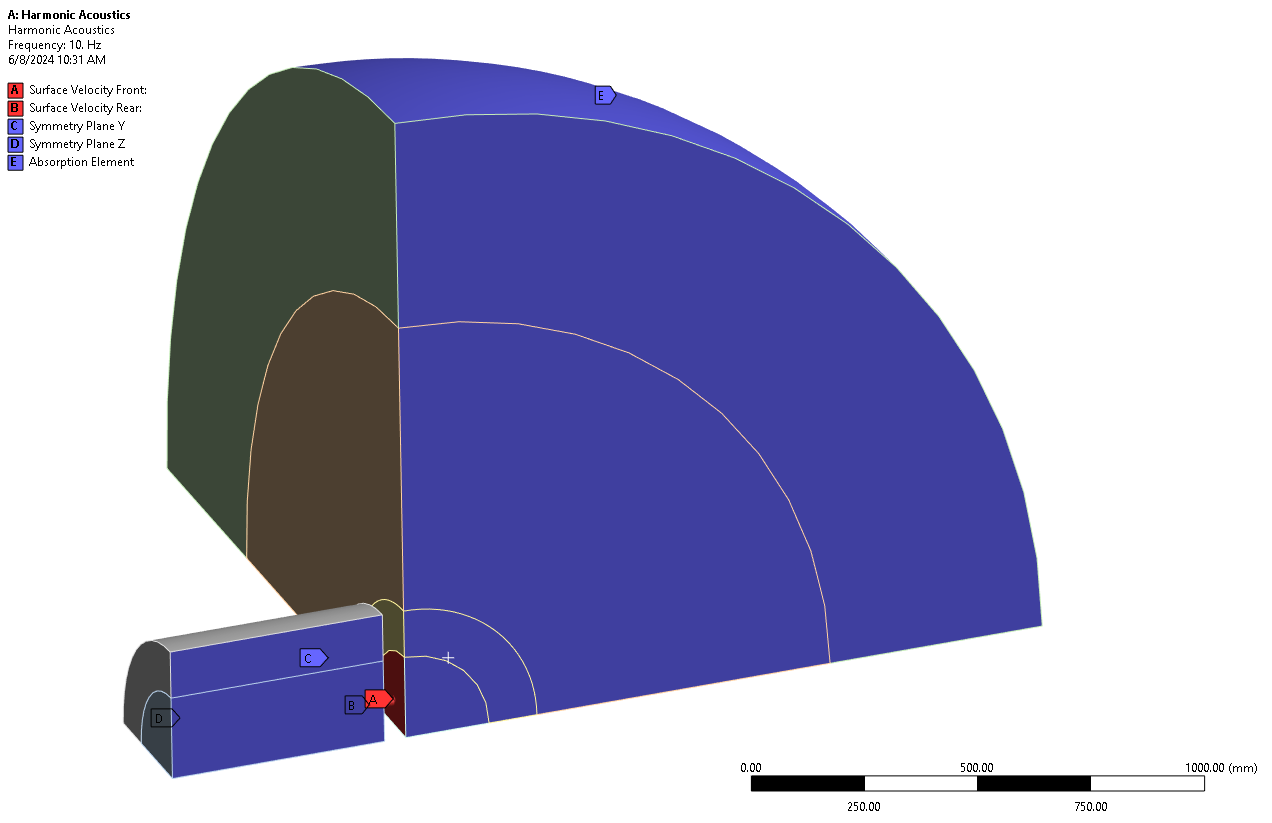

To include the results in our toolbox simulation we need to create an feaimport object.

% FEA import object:
feai 		= fea.feaimport;

% Add location of result files:
feai.fnamediaphragmf 	= fullfile(pwd,"ansysexport","closedboxvalpresfront.txt");
feai.fnamediaphragmr 	= fullfile(pwd,"ansysexport","closedboxvalpresrear.txt");

% Diaphragm velocity and area:
feai.xdot 				= 1e-3;
feai.sd 				= wf.sd;

We plot the acoustic impedance together with the previous analytical ones. The frequency range is changed to a maximum of 2kHz, because we have only run the simulation to this frequency.

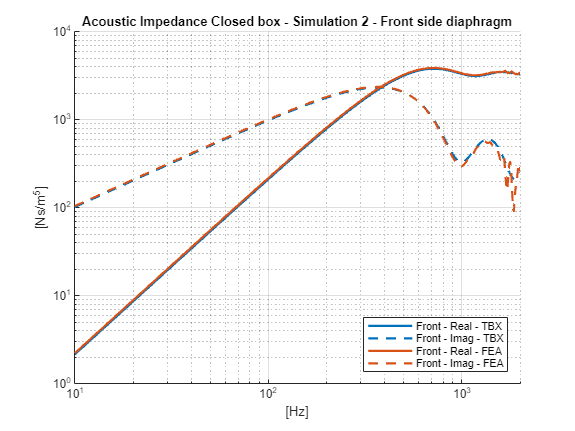

% Figure - Acoustic impedance - Front side
fig3				= figure;
ax3					= axes(fig3); hold on; grid on;
ax3.FontSize		= 8;
ax3.XScale			= "log";
ax3.XLim 			= [feai.fans(1) feai.fans(end)];
ax3.YScale			= "log";
ax3.Title.String	= "Acoustic Impedance Closed box - Simulation 2 - Front side diaphragm";
ax3.XLabel.String	= "[Hz]";
ax3.YLabel.String	= "[Ns/m^5]";

p1	= plot(ax3,sim1.f,real(za.front),LineWidth=1.5);
plot(ax3,sim1.f,imag(za.front),LineWidth=1.5,LineStyle="--",Color=p1.Color);

ax3.ColorOrderIndex = 2;

% Add the FEA results:
p2 = plot(ax3,feai.fans,real(feai.zafront),LineWidth=1.5);
plot(ax3,feai.fans,imag(feai.zafront),LineWidth=1.5,LineStyle="--",Color=p2.Color);

leg3 	= legend(ax3,"Front - Real - TBX","Front - Imag - TBX","Front - Real - FEA","Front - Imag - FEA");
leg3.Location 	= "southeast";

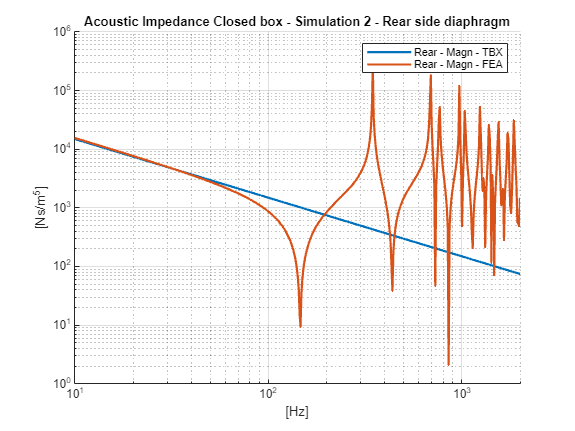


% Figure - Acoustic impedance - Rear side
fig4				= figure;
ax4					= axes(fig4); hold on; grid on;
ax4.FontSize		= 8;
ax4.XScale			= "log";
ax4.XLim 			= [feai.fans(1) feai.fans(end)];
ax4.YScale			= "log";
ax4.Title.String	= "Acoustic Impedance Closed box - Simulation 2 - Rear side diaphragm";
ax4.XLabel.String	= "[Hz]";
ax4.YLabel.String	= "[Ns/m^5]";

plot(ax4,sim1.f,abs(za.rear),LineWidth=1.5);

% Add the FEA results:
plot(ax4,feai.fans,abs(feai.zarear),LineWidth=1.5);

leg4 	= legend(ax4,"Rear - Magn - TBX","Rear - Magn - FEA");

A couple things to mention:

- The FEA front side impedance begins to roughen above 1kHz. In the other regions it is nearly similar to the toolbox impedance.

- The FEA rear side impedance shows the standing waves inside the cabinet. But before these are present, the slope and magnitude of the impedance is nearly similar to the toolbox impedance.

Questions: the modes shown for the rear impedance, are the calculated for the quarter symmetry model, or does ANSYS 'know' by applying a symmetry region that it must calculate it for a complete model? For example, the Hornresp unmasked pressure is as follows and has its first mode at 342Hz. 

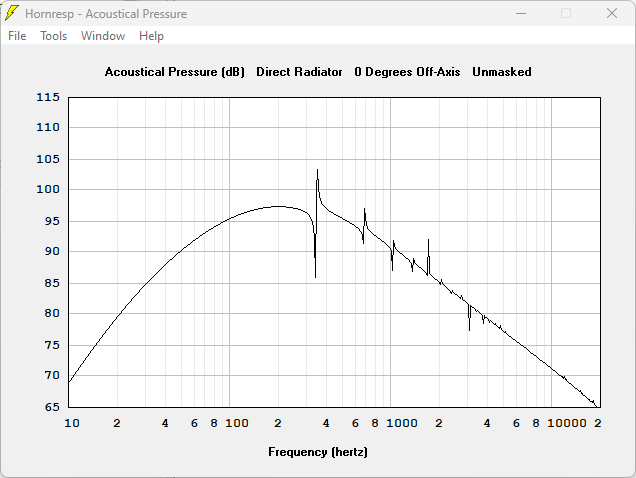

Sound pressure level:

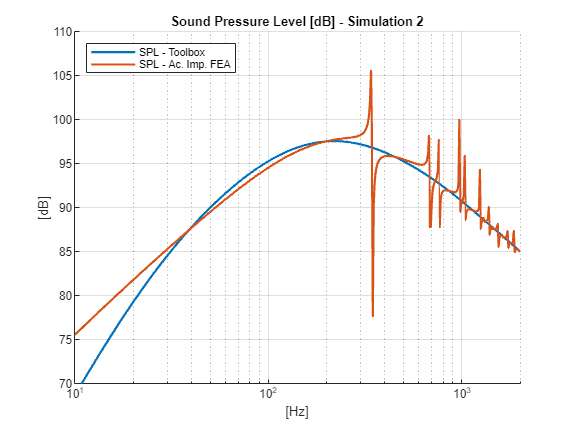

% Add the FEA import object to the simulation object:
sim2.feai 			= feai;

% Change the frequency of the simulation object to the frequency of the FEA
% object:
sim2.f 				= feai.fans;

% Calculate SPL [dB]:
spl2 				= sim2.spl;

% Figure 5 - SPL
fig5				= figure;
ax5					= axes(fig5); hold on; grid on;
ax5.FontSize		= 8;
ax5.XScale			= "log";
ax5.XLim 			= [sim2.f(1) sim2.f(end)];
ax5.YLim 			= ax2.YLim;
ax5.XLabel.String	= "[Hz]";
ax5.YLabel.String	= "[dB]";
ax5.Title.String	= "Sound Pressure Level [dB] - Simulation 2";

% Analytical:
plot(ax5,sim1.f,spl,LineWidth=1.5)

% FEA:
plot(ax5,sim2.f,spl2,LineWidth=1.5)

leg5 			= legend(ax5,"SPL - Toolbox","SPL - Ac. Imp. FEA");
leg5.Location 	= "northwest";

To be continued.

## Simulation 3

Question:

- Is it allowed to define a relationship between cone velocity and sound pressure at a certain microphone distance, and use this to calculate SPL for a system where the cone velocity is calculated using the acoustic impedances obtained from FEA?

We export a textfile from ANSYS, containing the pressure at a specific node at 1m distance.

% Simulation 3:
sim3 				= sim2;

% Add export file:
sim3.feai.fnamexdottopres 	= fullfile(pwd,"ansysexport","closedboxvalpresmic.txt");

Show results:

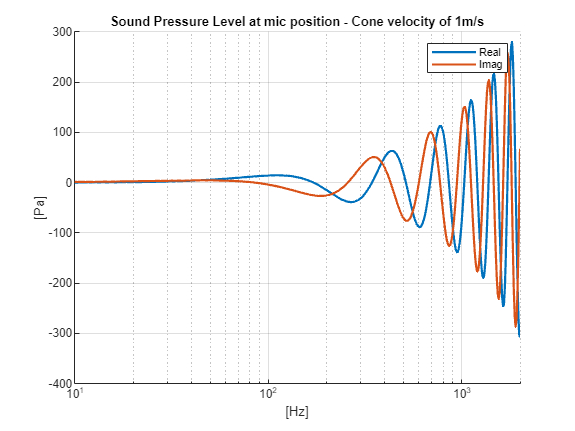

% Figure 6 - Pressure at 1m, for a cone velocity of 1m/s.
fig6 				= figure;
ax6 				= axes(fig6); hold on; grid on;
ax6.FontSize 		= 8;
ax6.XScale 			= "log";
ax6.XLim 			= [sim2.f(1) sim2.f(end)];
ax6.XLabel.String	= "[Hz]";
ax6.YLabel.String	= "[Pa]";
ax6.Title.String	= "Sound Pressure Level at mic position - Cone velocity of 1m/s";

xdot2pres 			= sim3.feai.xdot2pres;

plot(ax6,sim3.f,real(xdot2pres),LineWidth=1.5);
plot(ax6,sim3.f,imag(xdot2pres),LineWidth=1.5);

leg6 		= legend(ax6,"Real","Imag");

Show SPL, using this cone velocity - pressure relation:

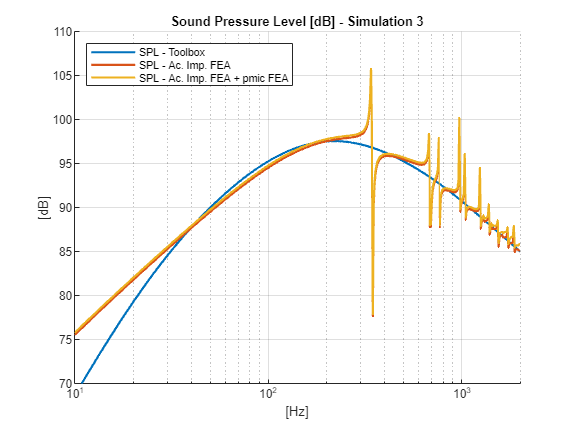

spl3 				= sim3.spl;

% Figure 7 - SPL
fig7				= figure;
ax7					= axes(fig7); hold on; grid on;
ax7.FontSize		= 8;
ax7.XScale			= "log";
ax7.XLim 			= [sim2.f(1) sim2.f(end)];
ax7.YLim 			= ax2.YLim;
ax7.XLabel.String	= "[Hz]";
ax7.YLabel.String	= "[dB]";
ax7.Title.String	= "Sound Pressure Level [dB] - Simulation 3";

plot(ax7,sim1.f,spl,LineWidth=1.5);
plot(ax7,sim2.f,spl2,LineWidth=1.5);
plot(ax7,sim3.f,spl3,LineWidth=1.5);

leg7 			= legend(ax7,"SPL - Toolbox","SPL - Ac. Imp. FEA","SPL - Ac. Imp. FEA + pmic FEA");
leg7.Location 	= "northwest";

This method seems valid!

## Appendix A - Hornresp inputs

To validate the results in this Livescript it is compared to results by hornresp: